## Construction of Root Locus Diagram

### definition of the transfer funcition  

close all
clear;
num = [2 1];   % defining numinator 
denum = [1 3 2 0];  % defining denuminator 
G = tf(num,denum)  % defining the transfer function

G =
 
       2 s + 1
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


### root locus 

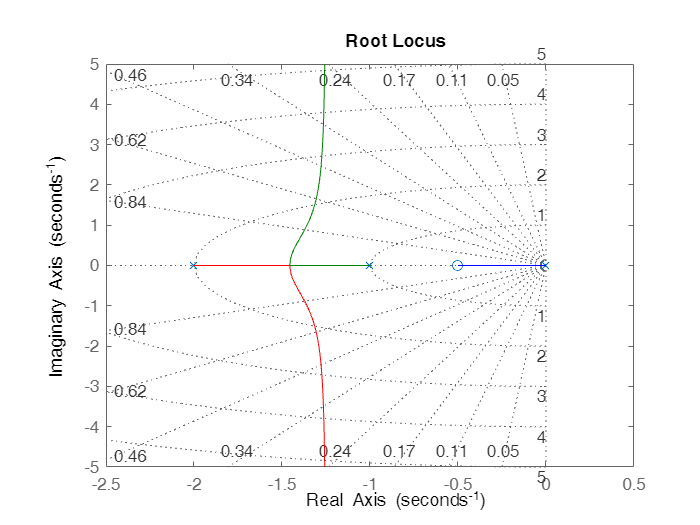

rlocus(G);
sgrid

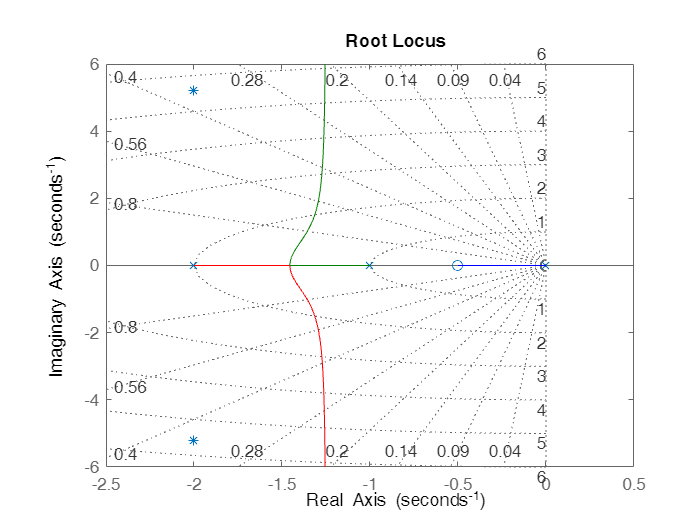

% root locus with desired poles 
figure();
rlocus(G);
hold on 
points = [-2 + 5.2j , -2-5.2j];
plot(points,'*')
sgrid
hold off